문제1

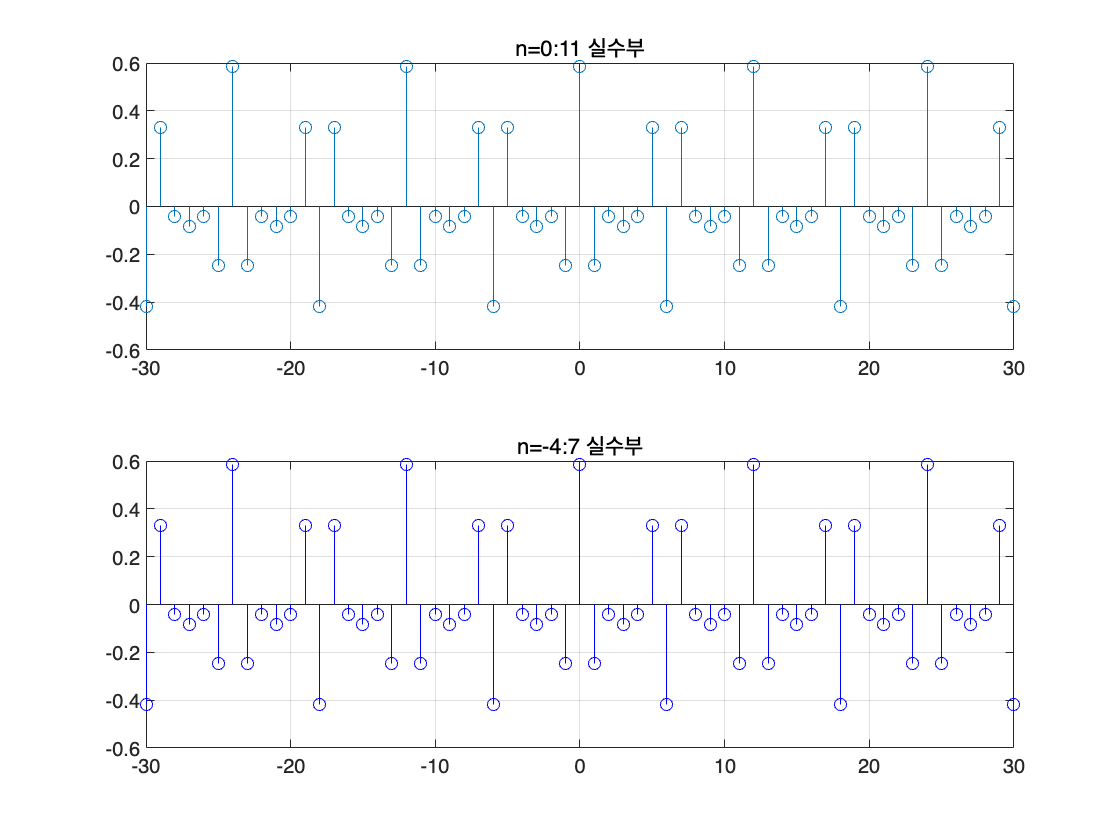

clear; close all; clc;
N = 12; % 주기
n1 = 0:11; 
x1 = [0 -1 1 1 0 3 0 1 0 1 0 1]; 
k = -30:30; % 주파수
%DTFS 
W = exp(-1j * 2 * pi / N * (n1') * k);
X1 = (1/N) * (x1 * W);

n2 = -4:7;
x2 = [x1(9:end) x1(1:8)]; 
W2 = exp(-1j * 2 * pi / N * (n2') * k);
X2 = (1/N) * (x2 * W2);
%시각화
figure;
subplot(2,1,1); stem(k, real(X1)); title('n=0:11 실수부'); grid on;
subplot(2,1,2); stem(k, real(X2), 'b'); title('n=-4:7 실수부'); grid on;

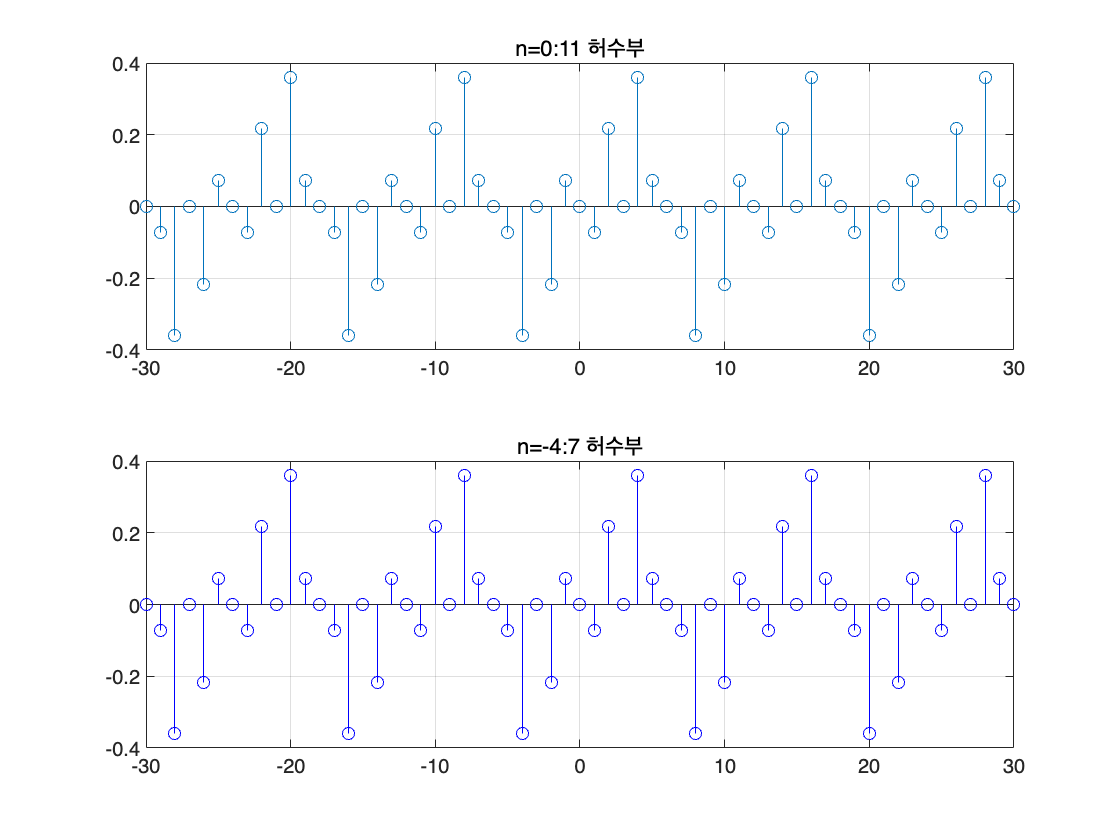

figure;
subplot(2,1,1); stem(k, imag(X1)); title('n=0:11 허수부'); grid on;
subplot(2,1,2); stem(k, imag(X2), 'b'); title('n=-4:7 허수부'); grid on;

x1,x2는 주기신호이므로 동일하게 나타남

문제2

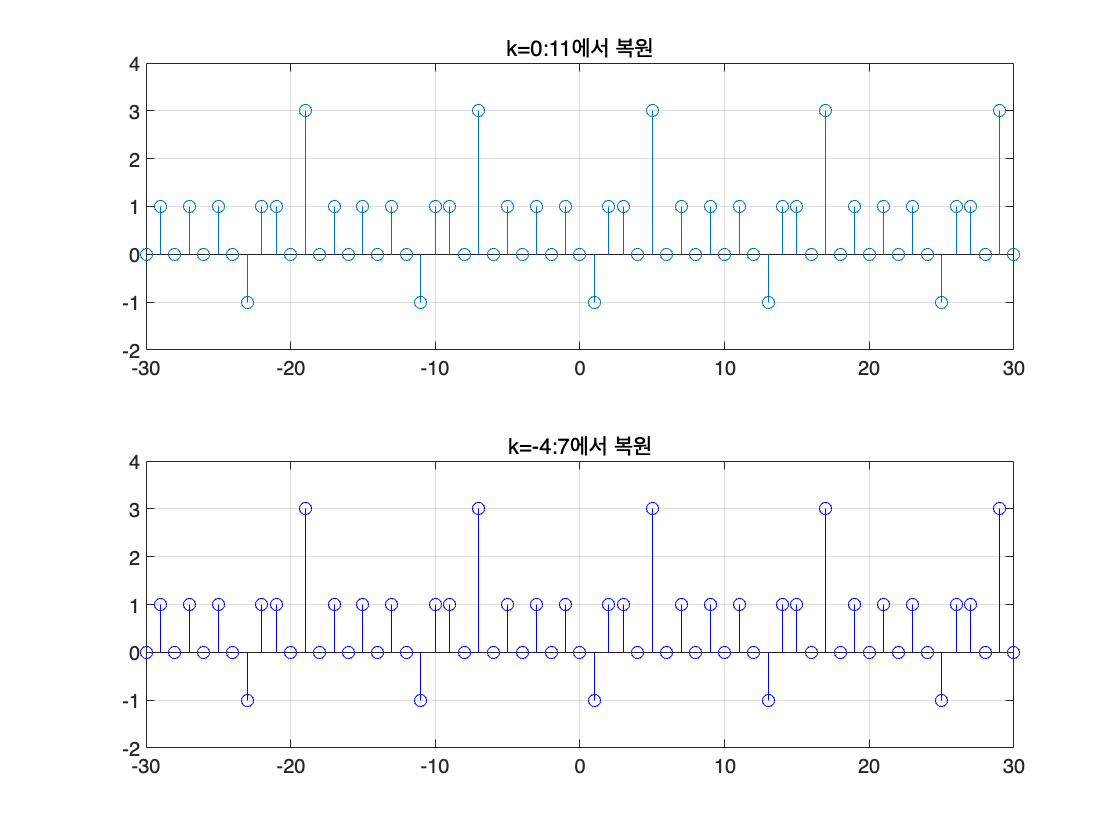

k0 = 0:11; 
Xk = (1/N) * (x1 * exp(-1j*2*pi/N * (n1') * k0));
m = -30:30; % 복원할 n값의 범위
% 첫 번째 케이스 
Emat1 = exp(1j * 2 * pi / N * (k0') * m); 
x1_rec = Xk * Emat1;
% 두 번째 케이스 
Xk2 = (1/N) * (x2 * exp(-1j*2*pi/N * (n2') * k0));
Emat2 = exp(1j * 2 * pi / N * (k0') * m);
x2_rec = Xk2 * Emat2;
%복원 신호 시각화(실수부)
figure;
subplot(2,1,1); stem(m, real(x1_rec)); title('k=0:11에서 복원'); grid on;
subplot(2,1,2); stem(m, real(x2_rec), 'b'); title('k=-4:7에서 복원'); grid on;

x1_rec, x2_rec는 각각 n=0:11, n=-4:7 구간에서의 역 DTFS 복원 결과.

실제 x[n]은 실수이므로 real(x1_rec)만 보면된다.

문제3

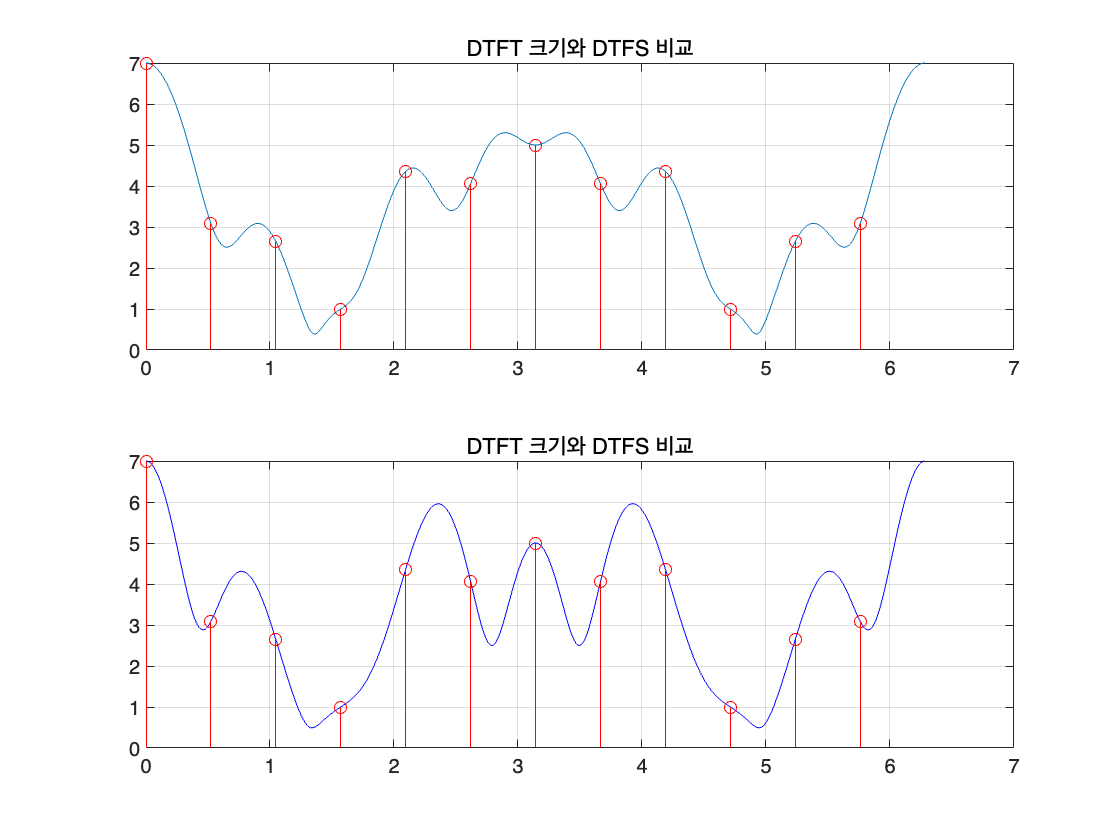

M = 1200; %DTFT 포인트 수
w = 2*pi*(0:M-1)/M; % 0~2pi, 1200포인트
% DTFT 계산 
Xw1 = x1 * exp(-1j * (n1') * w); 
% DTFT 계산 
Xw2 = x2 * exp(-1j * (n2') * w); 
% DTFS 샘플
w_sample = 2*pi*(0:N-1)/N; %DTFS가 정의되는 주파수 샘플
Xk_sample = N * Xk; 
idx_sample = round(w_sample/(2*pi)*M) + 1; 
%시각화
figure;
subplot(2,1,1);
plot(w, abs(Xw1)); hold on;
stem(w_sample, abs(Xk_sample), 'ro');
title('DTFT 크기와 DTFS 비교'); grid on;
subplot(2,1,2);
plot(w, abs(Xw2), 'b'); hold on;
stem(w_sample, abs(Xk_sample), 'ro');
title('DTFT 크기와 DTFS 비교'); grid on;

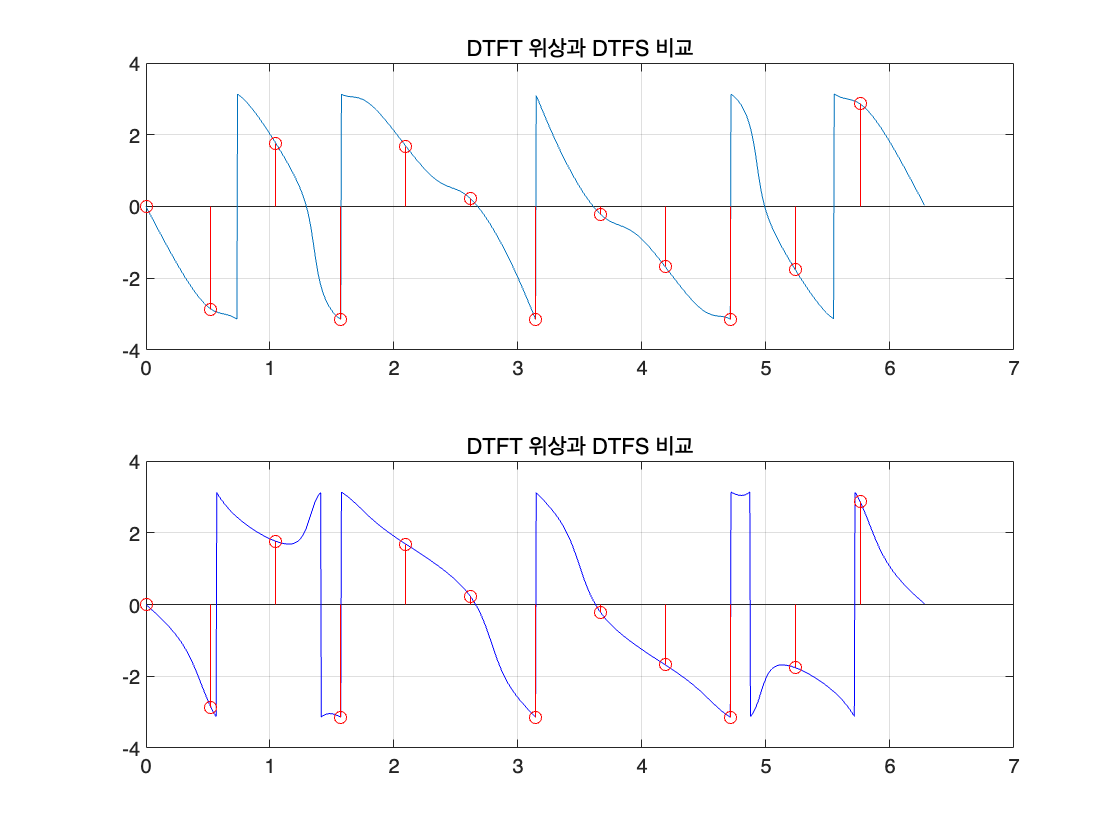


%DTFT와 DTFS 비교 시각화(위상)
figure;
subplot(2,1,1);
plot(w, angle(Xw1)); hold on;
stem(w_sample, angle(Xk_sample), 'ro');
title('DTFT 위상과 DTFS 비교'); grid on;
subplot(2,1,2);
plot(w, angle(Xw2), 'b'); hold on;
stem(w_sample, angle(Xk_sample), 'ro');
title('DTFT 위상과 DTFS 비교'); grid on;

시간구간을 다르게 하면 dtft의 위상만 변화하고 크기는 동일하다